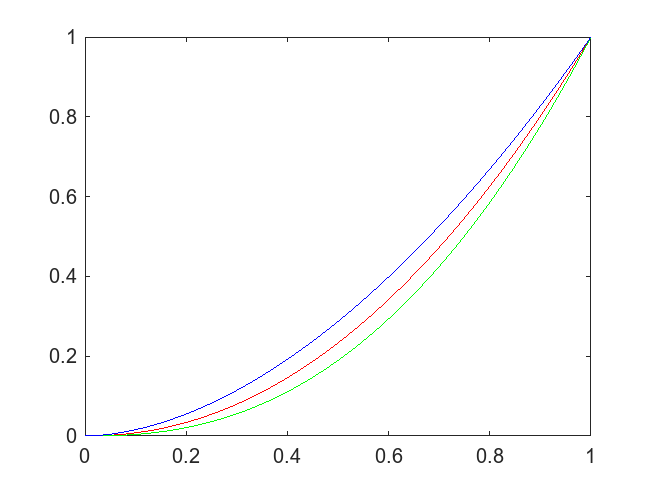

% 1.1
load("TRC_display.mat")

range = 0:0.01:1;

plot(range, TRCr, 'r')
hold on
plot(range, TRCg, 'g')
plot(range, TRCb, 'b')
hold off

**Answer:** As the blue curve has higher values than the other colors, the neutral colors will lean more towards a blueish tone.

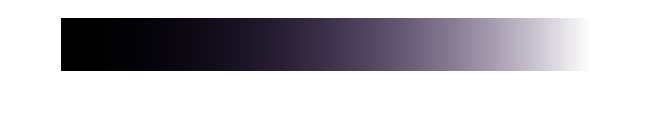

% 1.2
load("Ramp_display.mat")
load("Ramp_linear.mat")

imshow(Ramp_display)

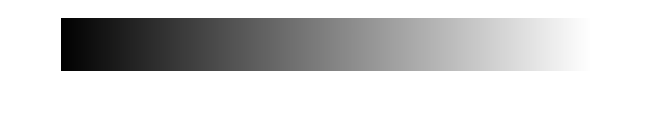

imshow(Ramp_linear)

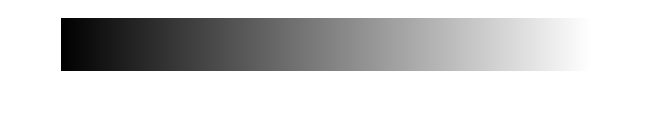


% Combine the TRC channels into the same matrix
TRC = cat(3, TRCr, TRCg, TRCb);

imshow(linearization(Ramp_display, range, TRC))

% 1.3
gammaRGB = [2.1, 2.4, 1.8];

imshow(gammaCorrection(Ramp_display, gammaRGB))

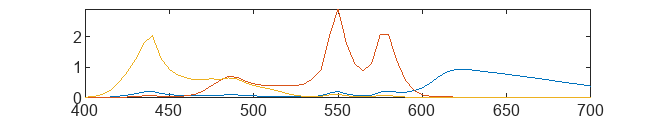

% 2.1
load("DLP.mat")

wavelength = 400:5:700;

plot(wavelength, DLP)

% 2.2
load("RGB_raw.mat")
load("XYZ_est.mat")
load("XYZ_ref.mat")
load("illum.mat")
load("chips20.mat")
load("xyz.mat")

% DLP is the projector, RGB_raw is raw RGB values from the camera,
% SRGB are the "final colors", k is the normalization factor,
% xyz is color matching functions, CIED65 is the light,
% XYZ_D65_ref is reference color measurements in the XYZ color space,
% e is the perceived difference between colors
SRGB = DLP*RGB_raw;

k = xyz(:, 2)' * CIED65';
k = 100./k;

XYZ_D65_ref = SRGB' * xyz * k;

e = computeDeltaE(XYZ_ref, XYZ_D65_ref');
mean(e)

ans = 22.3508

max(e)

ans = 51.6380

% 2.3
SRGB = DLP*RGB_cal_D65;

k = xyz(:, 2)' * CIED65';
k = 100./k;

XYZ_D65_ref = SRGB' * xyz * k;

e = computeDeltaE(XYZ_ref, XYZ_D65_ref');
mean(e)

ans = 16.9236

max(e)

ans = 33.5351

% 3.1

% c = ACRT * d';
% Trying to find d'

k = xyz(:, 2)' * CIED65';
k = 100./k;

ACRT = k * (DLP' * xyz)';

Dprim = inv(ACRT)*XYZ_est

Dprim =     0.7491    0.3818    0.0742    0.1615    0.0060    0.2044    0.7004    0.1009    0.5019    0.0495    0.2964    0.3718    0.2326    0.1363    0.1461    0.2187   -0.0912    0.4061    0.6730    0.3704
    0.5099    0.1543    0.0773    0.1217    0.4973    0.3095    0.4826    0.0399    0.3035    0.0311    0.0337    0.1004    0.0645    0.2549    0.2897    0.0426    0.3511    0.1029    0.5939    0.2922
    0.4799    0.2366    0.1327    0.1859    0.4524    0.3594   -0.0630    0.0501   -0.0584    0.0355    0.1350    0.0566    0.0862    0.0218    0.6421    0.1578    0.5430    0.0088    0.0092    0.3111


% 3.2
SRGB = DLP*Dprim;

k = xyz(:, 2)' * CIED65';
k = 100./k;

XYZ_D65_ref = SRGB' * xyz * k;

e = computeDeltaE(XYZ_ref, XYZ_D65_ref');
mean(e)

ans = 1.0238

max(e)

ans = 3.1053

**Answer:** Much smaller color difference than before.

% 3.3

**Answer:** Some values are negative.

% 3.4
Dprim(Dprim < 0) = 0;

SRGB = DLP*Dprim;

k = xyz(:, 2)' * CIED65';
k = 100./k;

XYZ_D65_ref = SRGB' * xyz * k;

e = computeDeltaE(XYZ_ref, XYZ_D65_ref');
mean(e)

ans = 2.8360

max(e)

ans = 17.8740

% 3.5
clf
plot_chrom_sRGB(ACRT)
hold on
plot_chrom_sRGB(SRGB)

**Answer:** It cannout reproduce all SRGB colors. We cut off negative values to 0 in this case, but this applies to colors outside the gamut [0,1].

% 3.5
e = computeDeltaE(XYZ_ref, XYZ_D65_ref')

e =     0.0337    2.3631    1.6165    1.1127    0.3276    1.0344   13.1729    0.2794   17.8740    1.5029    3.1053    1.4415    1.4043    0.9943    0.1533    0.8119    7.1737    0.9143    0.6314    0.7719


mean(e)

ans = 2.8360

max(e)

ans = 17.8740

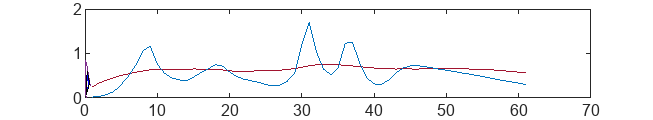


plot(chips20(1,:) .* CIED65)
hold on
plot(SRGB(:,1))